t1=0:0.001:2;

t2=0:0.001:1;

s1=(t1<1)&(t1~=0);

s2=(t2<=1/4)+(t2>=3/4)-1/2;

%Sketch the signal on the interval [0, 𝑇0].

figure;

plot(t1,s1);xlabel('t'),ylabel('s(t)');xlim([-0.2 2.2]);ylim([-0.2 1.2]);

plot(t2,s2);xlabel('t'),ylabel('s(t)');xlim([-0.05 1.05]);ylim([-0.55 0.55]);

**3.2.1 Synthesis of Periodic Signals **

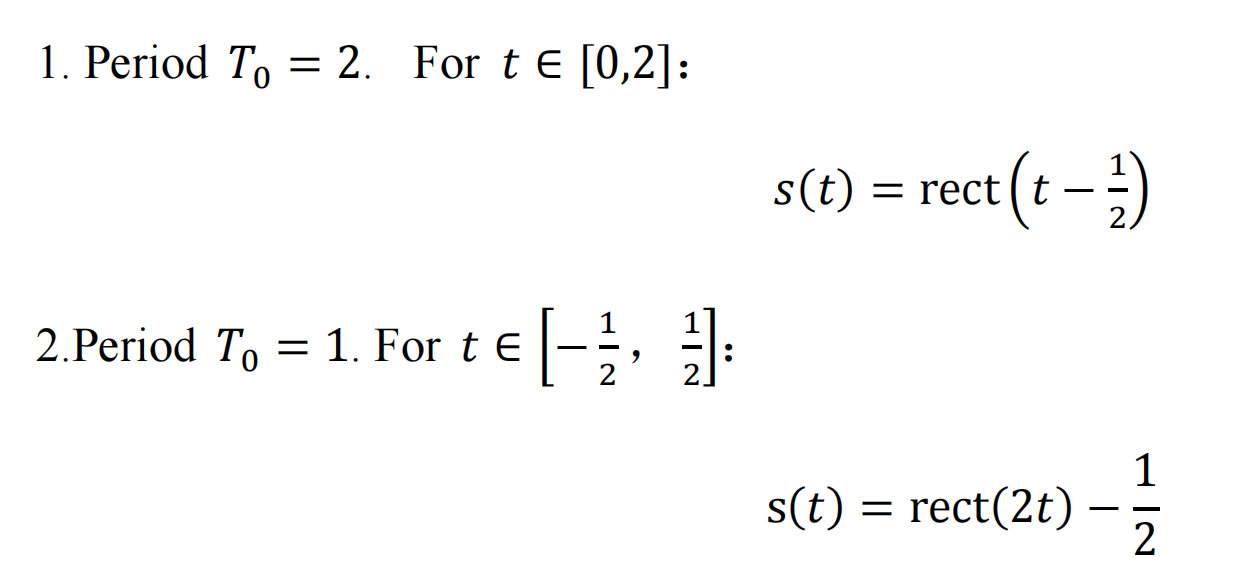

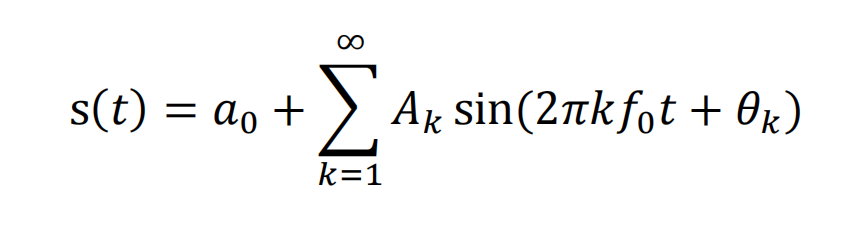

Signal 1: 𝑇0 = 2, 𝑠(𝑡) = rect(𝑡 − 1/2)

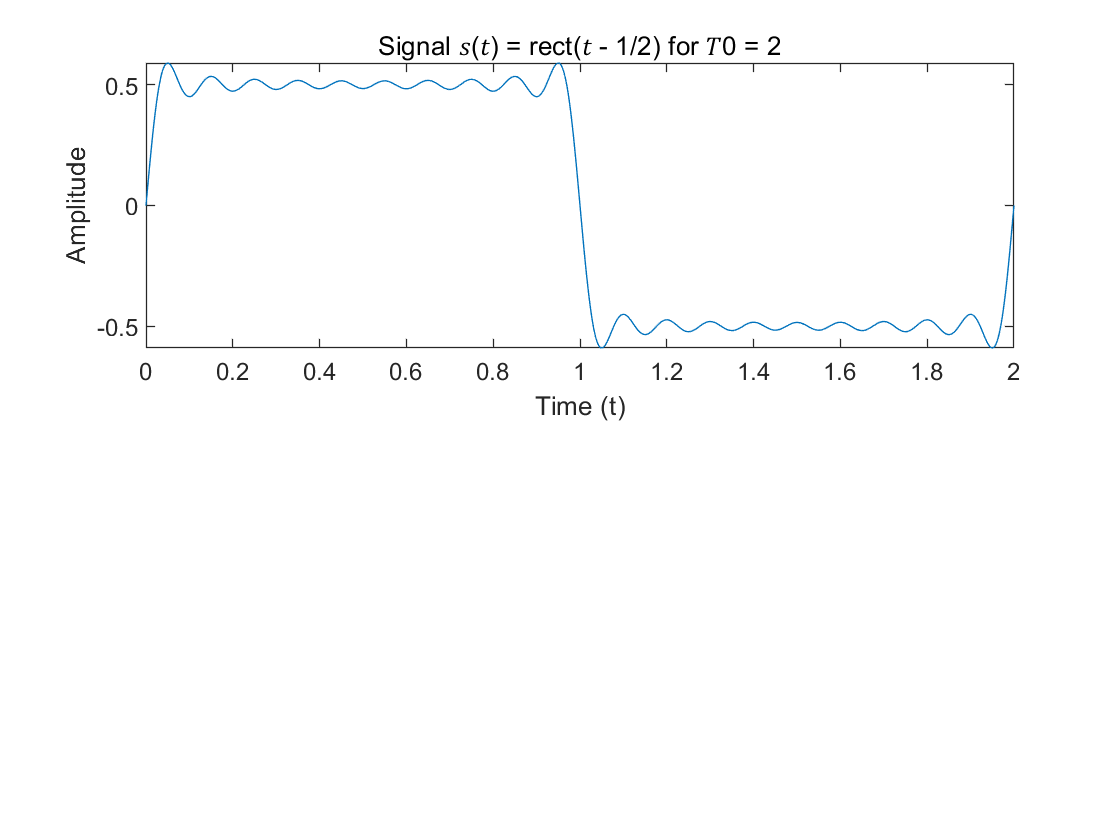

clear;
% Define signal parameters
T0_1 = 2; % Period
f0_1 = 1 / T0_1; % Fundamental frequency
t = linspace(0, T0_1, 1000); % Time vector for plotting

% Compute Fourier series coefficients
k_max = 10; % Number of terms in the series

s_t_1 = zeros(size(t)); % Initialize the signal

for k = 1:k_max
   
    % Construct the signal using the computed coefficients

    s_t_1=s_t_1+2*sin((2*k-1)*pi/2)/((2*k-1)*pi)*sin((2*k-1)*pi.*(t-0.5)+pi/2);
end

% Plot the signal
figure;
subplot(2, 1, 1);
plot(t, s_t_1);
title('Signal 𝑠(𝑡) = rect(𝑡 - 1/2) for 𝑇0 = 2');
xlabel('Time (t)');
ylabel('Amplitude');

Signal 2: 𝑇0 = 1, 𝑠(𝑡) = rect(2𝑡) - 1/2

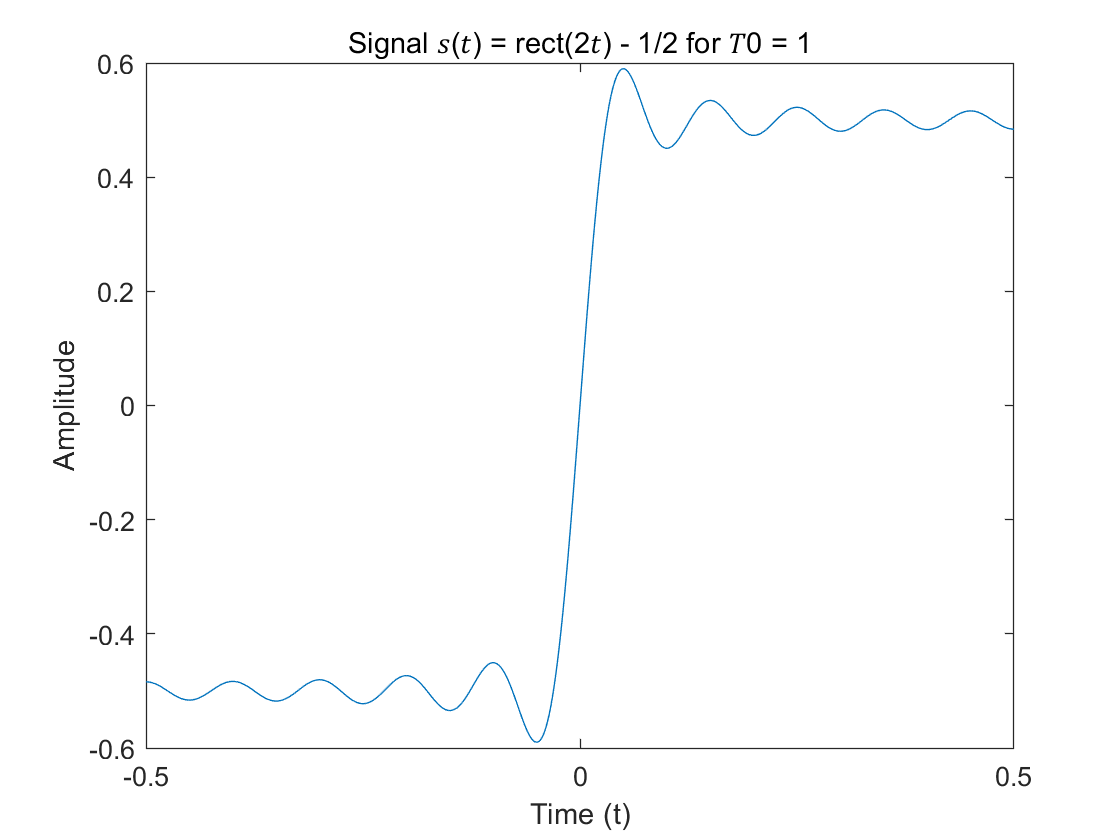

% Define signal parameters
T0_2 = 1; % Period
f0_2 = 1 / T0_2; % Fundamental frequency
t = linspace(-0.5, 0.5, 1000); % Time vector for plotting

% Compute Fourier series coefficients
k_max = 10; % Number of terms in the series

s_t_2 = zeros(size(t)); % Initialize the signal

for k = 1:k_max
   
    % Construct the signal using the computed coefficients
    s_t_2 = s_t_2 + 2*sin((2*k-1)*pi/2)/((2*k-1)*pi)*sin((2*k-1)*pi.*(t-0.5)+pi/2);
end

% Plot the signal
figure;

plot(t, s_t_2);
title('Signal 𝑠(𝑡) = rect(2𝑡) - 1/2 for 𝑇0 = 1');
xlabel('Time (t)');
ylabel('Amplitude');


% Plot the Fourier series coefficients A




**3.5.1 Discrete-Time Fourier Transform**

 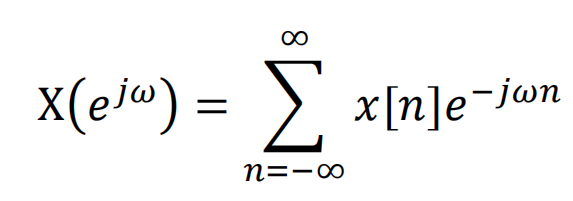

Since X(𝑒^ 𝑗𝜔)is a periodic function of ω with a period of 2𝜋, we need only to compute X(𝑒^ 𝑗𝜔)for −𝜋 < ω < π.

Here **n0 **is the time index corresponding to the 1st element of the **x **vector, and **dw **is the  

spacing between the samples of the Matlab vector **X**. For example, if **x **is a vector of length **N**, then  

its DTFT is computed by

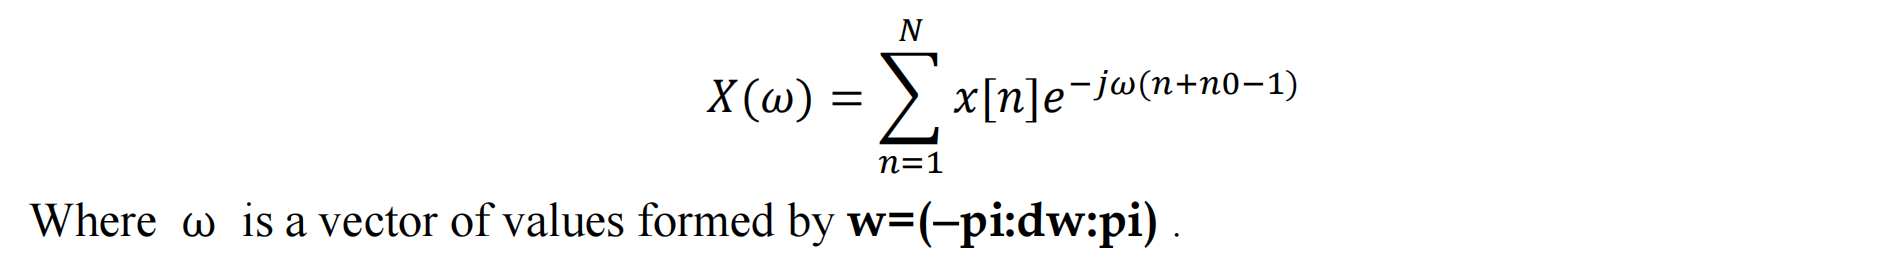

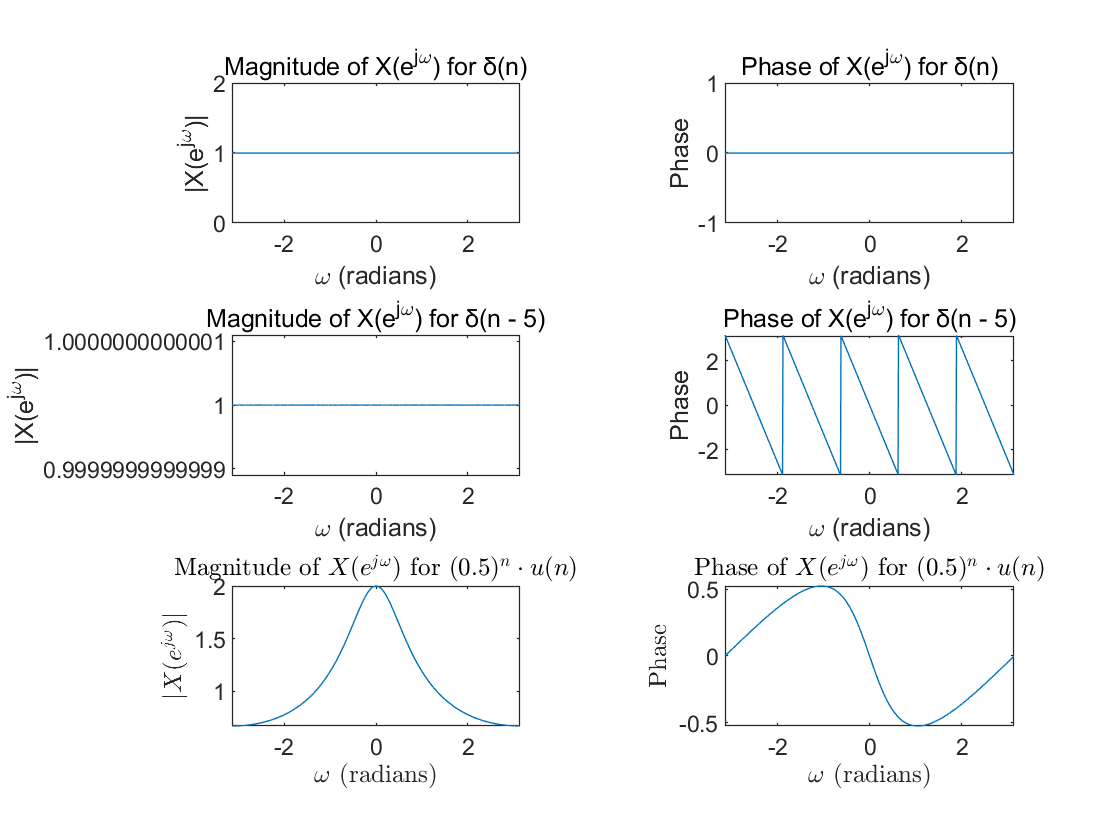

% Signal 1: x(n) = δ(n)
n = -10:10;
x1 = (n == 0); % Impulse signal
n0 = -10; % Starting index
dw = 0.01; % Frequency spacing

% Compute DTFT
X1 = DTFT(x1, n0, dw);

% Signal 2: x(n) = δ(n - 5)
n2 = -10:10;
x2 = (n2 == 5); % Impulse signal shifted to n = 5
n0 = -10; % Starting index
dw = 0.01; % Frequency spacing

% Compute DTFT
X2 = DTFT(x2, n0, dw);

% Signal 3: x(n) = (0.5)^n * u(n)
n3 = 0:20;
x3 = (0.5).^n3; % Exponential signal
n0 = 0; % Starting index
dw = 0.01; % Frequency spacing

% Compute DTFT
X3 = DTFT(x3, n0, dw);

% Create a 3x2 subplot for all six plots
figure;

% Plot Signal 1
subplot(3, 2, 1);
plot(-pi:dw:pi, abs(X1));
title('Magnitude of X(e^{j\omega}) for δ(n)');
xlabel('\omega (radians)');
ylabel('|X(e^{j\omega})|');

subplot(3, 2, 2);
plot(-pi:dw:pi, angle(X1));
title('Phase of X(e^{j\omega}) for δ(n)');
xlabel('\omega (radians)');
ylabel('Phase');

% Plot Signal 2
subplot(3, 2, 3);
plot(-pi:dw:pi, abs(X2));
title('Magnitude of X(e^{j\omega}) for δ(n - 5)');
xlabel('\omega (radians)');
ylabel('|X(e^{j\omega})|');

subplot(3, 2, 4);
plot(-pi:dw:pi, angle(X2));
title('Phase of X(e^{j\omega}) for δ(n - 5)');
xlabel('\omega (radians)');
ylabel('Phase');

% Plot Signal 3
subplot(3, 2, 5);
plot(-pi:dw:pi, abs(X3));
title('Magnitude of $X(e^{j\omega})$ for $(0.5)^n \cdot u(n)$', 'Interpreter', 'latex');
xlabel('$\omega$ (radians)', 'Interpreter', 'latex');
ylabel('$|X(e^{j\omega})|$', 'Interpreter', 'latex');

subplot(3, 2, 6);
plot(-pi:dw:pi, angle(X3));
title('Phase of $X(e^{j\omega})$ for $(0.5)^n \cdot u(n)$', 'Interpreter', 'latex');
xlabel('$\omega$ (radians)', 'Interpreter', 'latex');
ylabel('Phase', 'Interpreter', 'latex');